%% evidentierea performantelor
close all % se inchid ferestrele curente
h=tf(7, [3 1 10]); %se declara un element de ordinul II
k=7/10; % factorul de proportionalitate
wn=sqrt(10/3); % pulsatia naturala
df=1/3/2/wn; % factorul de amortizare
step(h); % afisarea raspunsului la treapta
hold; % retinerea afisarii curente

Current plot held



% suprareglajul
sigma=k*exp(-pi*df/sqrt(1-df^2));
% valoarea primului maxim
ymax=k*(1+exp(-pi*df/sqrt(1-df^2)));
% timpul de atingere al primului maxim
tmax=pi/wn/sqrt(1-df^2);
% plasare punct in maxim
plot(tmax,ymax,'.b','MarkerSize',20);
% plasare linie verticala prin maxim
plot([tmax tmax],[0 ymax],'--')
% evidentiere linie limita valoare stationara
plot([0 tmax],[ymax ymax],'--')
% formula text pentru maxim
s='$y_{max}=k(1+e^\frac{-\pi\xi}{\sqrt{1-\xi^2}})$'

s = '$y_{max}=k(1+e^\frac{-\pi\xi}{\sqrt{1-\xi^2}})$'

text(tmax+0.5,ymax,s,'Interpreter','Latex','FontSize',40);
% formula text pentru timp atingere maxim
s='$t_{max}=\frac{\pi}{\omega_n\sqrt{1-\xi^2}} $'

s = '$t_{max}=\frac{\pi}{\omega_n\sqrt{1-\xi^2}} $'

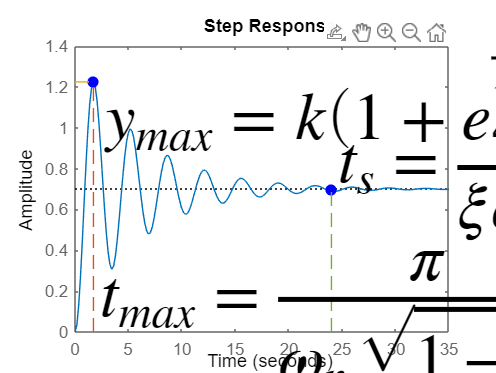

text(tmax,0.1,s,'Interpreter','Latex','FontSize',40);
% timpul de raspuns
ts=4/df/wn;
% text formula timp de raspuns
s='$t_s=\frac{4}{\xi\omega_n}$';
text(4/df/wn,k+0.1,s,'Interpreter','Latex','FontSize',40,'FontWeight','bold');
plot(4/df/wn,k,'.b','MarkerSize',20);
plot([4/df/wn 4/df/wn],[0 k],'--');shg